# Настройка на линейный оптимум контура тока

load("data.mat")

#### Синтез системы управления с ПИ-регулятором

С ПИ-регулятором мы будем синтезировать систему управления током.

Рассмотрим применение ПИ-регулятора на примере управления контуром тока. Будем производить настрйоку на линейный оптимум.

syms Tu L R s

crl.Wob = 1/(L*s+R);

Tu = L/R;
crl.Wol = 1/(Tu*s);

crl.Wreg = crl.Wol/(crl.Wob);
disp(collect(crl.Wreg,s))

$$\frac{\left(L\,R\right)\,s+R^{2}}{L\,s}$$

#### Моделирование работы системы настроенной на линейный оптимум

To = 0.1*Tu

crl.Tu = ob.L/ob.R;

crl.Ki_an = ob.R/crl.Tu;
crl.Kp_an = ob.L/crl.Tu;

crl.Ki_dg = ob.R/crl.Tu;
crl.Kp_dg = ob.L/crl.Tu;

Tmdl = 0.03;

To = 0.1*ob.L/ob.R;

warning off
SimNew = sim('lab3p3a_pi.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab3p3a_pi/crl.Kp_an
lab3p3a_pi/Sum3
lab3p3a_pi/Electric Drive/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p3a_pi/Electric Drive/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p3a_pi/Sum (algebraic variable)
Found algebraic loop containing: 
lab3p3a_pi/crl.Kp_dg


warning on

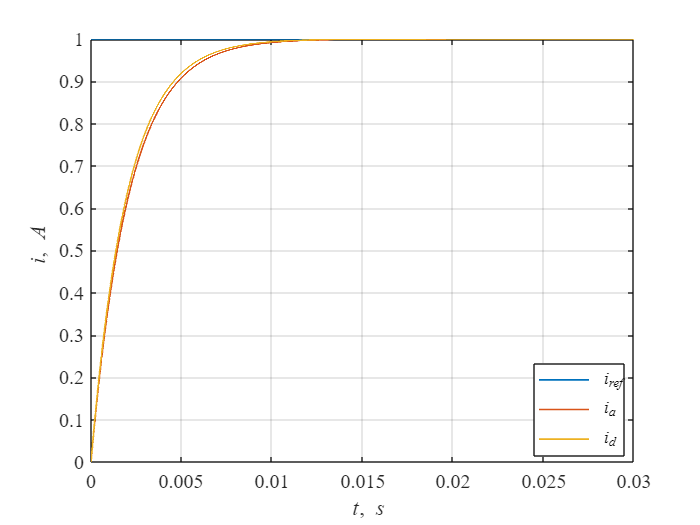

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','Location','best')

В данной ситуации системы близки друг к другу и можно ничего не делать и не пользоваться методом переоборудования.

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 2.8*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 2.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


#### Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового ПИ-регулятора для случая вычислительной задержки epslison=0

clear Tzap f
To = crl.Tu;
Tmdl = 0.1;
for i = 1:10
    crl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = crl.Tz;
    warning off
    SimNew = sim('lab3p4_pi.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.ia(:,1);
    ia = SimNew.ia(:,3);
    id = SimNew.ia(:,4);
    f(i) = trapz(t,abs(id-ia));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
lab3p4_pi/crl.Kp_dg
lab3p4_pi/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p4_pi/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p4_pi/A//D C1
lab3p4_pi/Sum3 (algebraic variable)
lab3p4_pi/crl.Ki_dg
lab3p4_pi/i trap1/Gain2


Теперь строим график и ищем минимум функционала

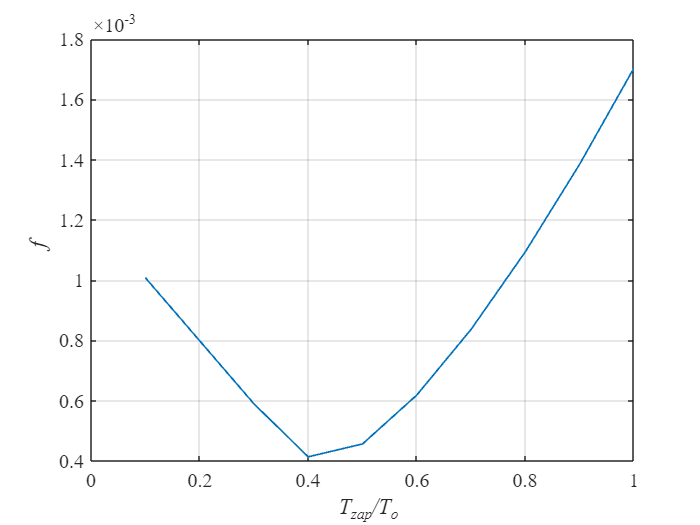

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

To = Te

crl.Tz = 0.4*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Ki_an = ob.R/crl.Tu;
crl.Kp_an = ob.L/crl.Tu;

crl.Ki_dg = ob.R/crl.Tu;
crl.Kp_dg = ob.L/crl.Tu;

Tmdl = 0.05;
To = ob.L/ob.R;

warning off
SimNew = sim('lab3p4_pi.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab3p4_pi/crl.Kp_dg
lab3p4_pi/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p4_pi/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p4_pi/A//D C1
lab3p4_pi/Sum3 (algebraic variable)
lab3p4_pi/crl.Ki_dg
lab3p4_pi/i trap1/Gain2


warning on

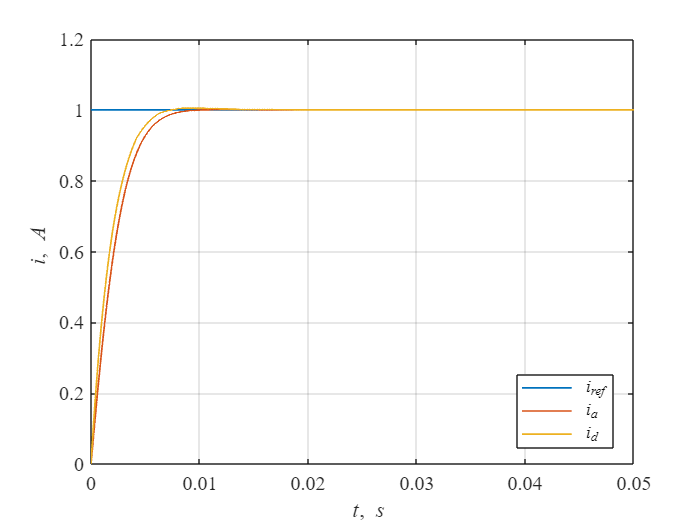

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 1.7*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 1.7*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.5%


#### Синтез системы управления с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового ПИ-регулятора для случая вычислительной задержки e=To

clear Tzap f
To = crl.Tu;
Tmdl = 0.1;
for i = 1:20
    crl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = crl.Tz;
    warning off
    SimNew = sim('lab3p5_pi.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.ia(:,1);
    ia = SimNew.ia(:,3);
    id = SimNew.ia(:,4);
    f(i) = trapz(t,abs(id-ia));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

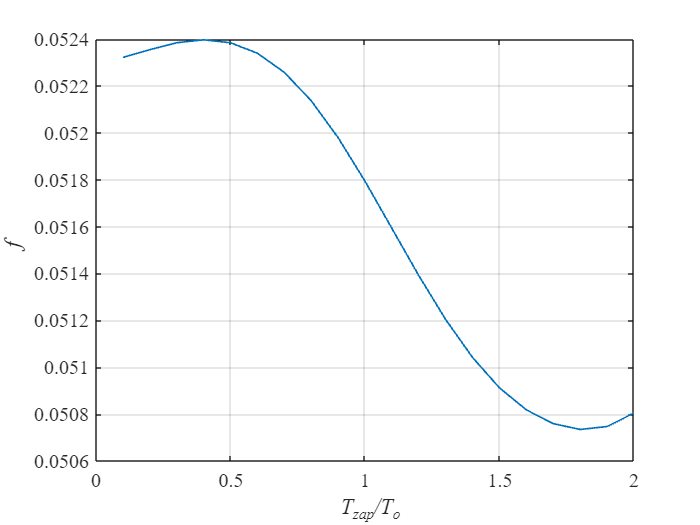

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

To = Te

Tmdl = 0.1;
To = ob.L/ob.R;

crl.Tz = 1.8*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Ki_an = ob.R/crl.Tu;
crl.Kp_an = ob.L/crl.Tu;

crl.Ki_dg = ob.R/crl.Tu;
crl.Kp_dg = ob.L/crl.Tu;

warning off
SimNew = sim('lab3p5_pi.slx','ReturnWorkspaceOutputs', 'on');
warning on

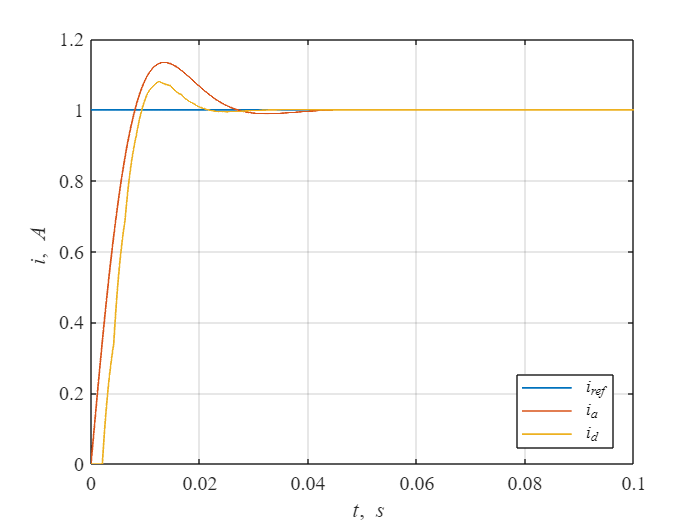

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 1.5*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 2.7*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 8.1%
